# Effect of Cpd31 on Nocodazole-induced Rho activity

Code related to Figure S8C in Marshall-Burghardt et. al., 2024, Science Advances

Written by Rodrigo Migueles Ramirez, McGill University, Montreal, 2024

Before running this script, each dataset must have gone through the following scripts:

✅ Setup

✅ Preprocessing

✅ FRET

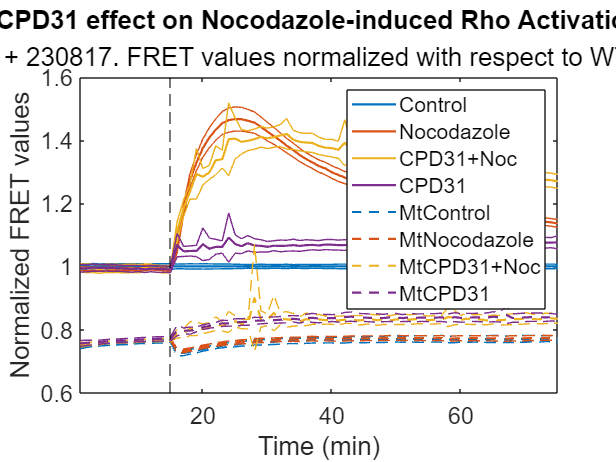

load("Supplement\FigS8\Results\23081617-allTrends.mat", "allTrends");

for c = 1
    control = zeros(75,16);
    noc =   zeros(75,32);
    cpdnoc = zeros(75,16);
    cpd = zeros(75,16);
    
    mtcontrol = zeros(75,16);
    mtnoc =   zeros(75,32);
    mtcpdnoc = zeros(75,16);
    mtcpd = zeros(75,16);
    
    control(1:75, 1:4) = allTrends(:,1:4,1);
    control(1:75, 5:8) = allTrends(:,1:4,2);
    control(1:75, 9:12) = allTrends(:,1:4,3);
    control(1:75, 13:16) = allTrends(:,1:4,4);
    control = control';
    
    noc(1:75, 1:8) = allTrends(:,5:12,1);
    noc(1:75, 9:16) = allTrends(:,5:12,2);
    noc(1:75, 17:24) = allTrends(:,5:12,3);
    noc(1:75, 25:32) = allTrends(:,5:12,4);
    noc = noc';
    
    cpdnoc(1:75, 1:4) = allTrends(:,13:16,1);
    cpdnoc(1:75, 5:8) = allTrends(:,13:16,2);
    cpdnoc(1:75, 9:12) = allTrends(:,13:16,3);
    cpdnoc(1:75, 13:16) = allTrends(:,13:16,4);
    cpdnoc = cpdnoc';
    
    cpd(1:75, 1:4) = allTrends(:,17:20,1);
    cpd(1:75, 5:8) = allTrends(:,17:20,2);
    cpd(1:75, 9:12) = allTrends(:,17:20,3);
    cpd(1:75, 13:16) = allTrends(:,17:20,4);
    cpd = cpd';
    
    mtcontrol(1:75, 1:4) =   allTrends(:,21:24,1);
    mtcontrol(1:75, 5:8) =   allTrends(:,21:24,2);
    mtcontrol(1:75, 9:12) =  allTrends(:,21:24,3);
    mtcontrol(1:75, 13:16) = allTrends(:,21:24,4);
    mtcontrol = mtcontrol';
    
    mtnoc(1:75, 1:8) =   allTrends(:,25:32,1);
    mtnoc(1:75, 9:16) =  allTrends(:,25:32,2);
    mtnoc(1:75, 17:24) = allTrends(:,25:32,3);
    mtnoc(1:75, 25:32) = allTrends(:,25:32,4);
    mtnoc = mtnoc';
    
    mtcpdnoc(1:75, 1:4) =   allTrends(:,33:36,1);
    mtcpdnoc(1:75, 5:8) =   allTrends(:,33:36,2);
    mtcpdnoc(1:75, 9:12) =  allTrends(:,33:36,3);
    mtcpdnoc(1:75, 13:16) = allTrends(:,33:36,4);
    mtcpdnoc = mtcpdnoc';
    
    mtcpd(1:75, 1:4) =   allTrends(:,37:40,1);
    mtcpd(1:75, 5:8) =   allTrends(:,37:40,2);
    mtcpd(1:75, 9:12) =  allTrends(:,37:40,3);
    mtcpd(1:75, 13:16) = allTrends(:,37:40,4);
    mtcpd = mtcpd';
end

conditions = {control; noc; cpdnoc; cpd; mtcontrol; mtnoc; mtcpdnoc; mtcpd};
conditions_str = {'Control'; 'Nocodazole'; 'CPD31+Noc'; 'CPD31'; 'MtControl'; 'MtNocodazole'; 'MtCPD31+Noc'; 'MtCPD31';};

i = 1;
cmap = lines(4);
cmap(5:8,:) = cmap(1:4,:);
figure; 
for c = 1 : length(conditions)
    for frame = 1:75
        pd = fitdist(conditions{c}(:,frame),'Normal'); 
        ci = paramci(pd);
        upperCI(c, frame) = ci(2,1);
        lowerCI(c, frame) = ci(1,1);            
    end
    u(i) = plot(upperCI(c,:), 'LineWidth', 0.5, 'Color', cmap(c,:)); 
    hold on;
    l(i) = plot(lowerCI(c,:), 'LineWidth', 0.5, 'Color', cmap(c,:)); 
    p(i) = plot(mean(conditions{c}, 1), 'LineWidth', 1.5, 'Color', cmap(c,:));
    if i >= 5
        p(i).LineStyle = '--';
        u(i).LineStyle = '--';
        l(i).LineStyle = '--';
    end
    i = i + 1;
end
xline(15, '--k');
legend(p(1:8), conditions_str);
xlim([1,75]);
xlabel('Time (min)');
ylabel('Normalized FRET values');
title('CPD31 effect on Nocodazole-induced Rho Activation');
subtitle('230816 + 230817. FRET values normalized with respect to WT Control.');
ax = gca;
ax.FontSize = 16;